# MEEM 4730 Project #1

Ross Smyth

This report describes Project #1 from the class MEEM 4730, Dynamic Systems Simulation. For this project two integrators were implemented in MATLAB using functions, and with those integrators three systems were evalauted. The specific integrators used were forward Euler ("Euler"), Second Order Adams-Bashforth ("AB2"), and fourth-order Runge-Kutte ("RK4"). This are listed in their theoretical least accurate, to most accurate. They all rely on the derivitives of the system, and the past data to calculate each subsequent value(s). They are able to solve not just linear time invariant ODE's, but also time-varying and non-linear systems of differential equations. 

First i shall describe the code that was implemented, and it is also avalible in the directory that holds this document. Then I will describe the verification and validation efforts for ensuring the integrators are correct. The programming itself was fairly straight-forward as the equations are easily accessible from notes or only, the validaation was done against an ODE with a closed form solution, the verification was done against other students' data who are also working on this project. Theoretically the verification step could fail if we all make the same mistake, but that is improbable.

## Implementation

In this section I will describe the implementation of the integrators, the systems, and the file for processing these.

### Second Order Adams-Bashforth

This integrator was the first one that was not given with the assignment (Euler was). It is very similar to the Euler function, but it intializes the array differently and the integration scheme itself is different.

- Lines 33-36 unpack the state-variables representation of the differential equations to  local definitions. 

- Line 40 pre-allocates to the size that will be output arrays that are all zero and the correct size by calling initArrays, a provided function with this assignment.

- Lines 44-46 set the initial conditions (IC) as described either by the IC passed into the function, or by the returned values by the state-variable functions.

- Lines 50-52 calculate the first value via forward Euler integration. This is because AB-2 integration looks at the past 2 values, and so at least 1 value past the initial conditions must be known.

- Lines 56-64 integrate the system, which will be detailed below

- First the following equation is implemented, which is the AB2 formula. $x_n$ represents the current value being calculated, h represents the time step, and f represents the state-variables function mapping the states to their derivatives.


$$x_n =x_{n-1} +\frac{1}{2}h\left(3f_{n-1} -f_{n-2} \right)$$


7. Next the input is assigned to it's current value (the value that affects the next step)

8. The states are mapped to the output

This is very similar to the Euler integration provided, but it instead looks back two data points rather than just one. 

###  Fourth-Order Runge-Kutte Integration

This integrator is techinically a higher-level version of Euler integration, or it could be said that Euler is a first-order implementation of  Runge-Kutte. Simlar to Euler it only requires the previous states rather than more than one. 

- Lines 34-47 are the same as AB2's lines 33-46

- Next is the actual simulation loop

- First the current derivative is calcualted and stored

- Next the derivative one-half of a time step ahead is calculated

- Then the same time step is calculated, except at a higher point at attempt to reduce error

- Then the derivative at the next time step is calcualted

- These are combined via a weighted average

- The loop continues until the end

The following equations describes the integration calculation. Rather than $x_{n+1}$ that is commonly seen in notation, $x_n$will represent the currently calculated data point to enforce that this procedure only requires the previous data point, and not the future one (though it does require the future derivative).


$$\left\lbrace \begin{array}{l}
f\left(x,u,t\right)=\dot{x} \\
k_1 =f\left(x_{n-1} ,u_{n-1} ,t_{n-1} \right)\\
k_2 =f\left(x_{n-1} +\frac{h\;k_1 }{2},\;u_{n-1} \left(t_{n-1} +\frac{h}{2}\right),{\;t}_{n-1} +\frac{h}{2}\right)\\
k_3 =f\left(x_{n-1} +\frac{h\;k_2 }{2},{\;u}_{n-1} \left(t_{n-1} +\frac{h}{2}\right),\;t_{n-1} +\frac{h}{2}\right)\\
k_4 =f\left(x_{n-1} +h\;k_3 ,\;u_{n-1} \left(t_{n-1} +h\right),{\;t}_{n-1} +h\right)\\
x_n =x_{n-1} +\frac{h}{6}\left(k_1 +2\;k_2 +2\;k_3 +k_4 \right)
\end{array}\right.$$


These equations map 1:1 with lines 55-61 (discluding whitespace).

### State-Transition Functions

This section shall describe the function that implement the state-transition functions.

#### f2

This function takes in the previous state, and calculates the next state's derivative for integration. Specifically this is for a mass-spring-damper system with a time-varying spring constant. The differential equation describing this system is the following:


$$m\ddot{w} +c\dot{w} +k\left(t\right)w\left(t\right)=u\left(t\right)$$


- Lines 18 and 19 intilize the constant values (mass and damping)

- Lines 20 calculates the value of the time-varying parameter at this instant in time

- Next they are all combine in a way implementing the following equation:


$$f_2 =\left\lbrack \begin{array}{c}
\dot{x_1 } \\
\dot{x_2 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
-\frac{k\left(t\right)}{m} & -\frac{c}{m}
\end{array}\right\rbrack x+\left\lbrack \begin{array}{c}
0\\
\frac{1}{m}
\end{array}\right\rbrack u$$


This equation is similar to the classical state-space transition matrix equation, but it has a time-varying parameter so it requires more calculations.

#### f3

This function implements the Van der Pol Oscillator's state-transition function. The inputs are the current state, the current input, and the current time. It outputs the derivative of the system at the time. The following differential equation describes the system:


$$\ddot{w} -\mu \left(1-w^2 \right)\dot{w} +w=u$$


- Line 18 initilizes a constant, mu

- The final line calculates the derivative, but it has non-linear parameters so it is not able to be represented as a linear state-space equation. The following non-linear equation is what is implemented:


$$f_3 =\left\lbrack \begin{array}{c}
\dot{x_1 } \\
\dot{x_2 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
-1 & \left(1-x_1^2 \right)
\end{array}\right\rbrack x+\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack u$$


Which is not able to be represented with a linear equation.

#### simTest.m

This script was modified for convinience of viewing the integrators once each one was finished. It was modified from the given variant, to a variant that runs all the integrators for eahc system, and plots each in their own window. The helper function `plotData` was modified to accept different titles for each system. One the title's first line is the differential equation and initial conditions of the system, the secon dline is the integrator used. The entire script is shown in Appendix A.

#### Others

The other functions describing the state-variables representation of the system are straight forward regurjutation of the equation into a line. It is assumed that the reader can intepret that successfully. The fuctions include y2, y3, u2, and u3.

## Verification and Validation

### Validation

To validate the integrators, a differential equation with a known closed-form solution was simulated. The differential equation is the folllowing:


$$\begin{array}{l}
\dot{x} =-4x+u\left(t\right)\\
y=x\\
u\left(t\right)=0
\end{array}$$


The integrators are shown below with the validated solution. The input is not shown as the as it is zero for all times and values.

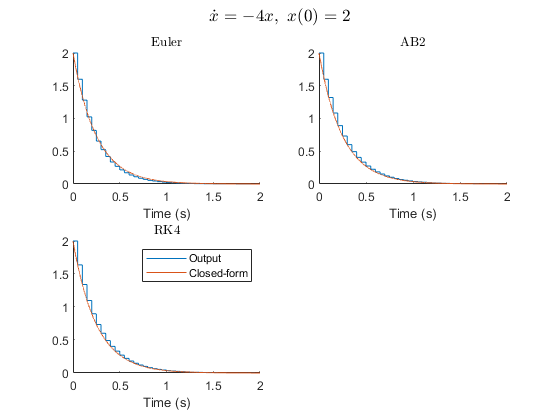

s1 = {@f1,@y1,@u1,2.0};
expo = "$\dot{x} = -4x, \; x(0) = 2$";

[OutE.t,  OutE.y,  OutE.u]     = mySim(s1, 2.0, 0.05, 'euler');
[OutAB.t, OutAB.y, OutAB.u]    = mySim(s1, 2.0, 0.05, 'ab2');
[OutRK4.t, OutRK4.y, OutRK4.u] = mySim(s1, 2.0, 0.05, 'rk4');

validTime = 0:0.0001:2;
validData = 2 * exp(-4 * validTime);

figure()
subplot(2, 2, 1)
sgtitle(expo, 'Interpreter','latex')

hold on
title("Euler", 'Interpreter','latex')
[x, y] =   stairs(OutE.t, OutE.y);
plot(x, y)
plot(validTime, validData)

xlabel("Time (s)")
hold off

subplot(2, 2, 2)
hold on
title("AB2", 'Interpreter','latex')

[x, y] =   stairs(OutAB.t, OutAB.y);
plot(x, y)
plot(validTime, validData)

xlabel("Time (s)")
hold off

subplot(2, 2, 3)
hold on
title("RK4", 'Interpreter','latex')

[x, y] =   stairs(OutRK4.t, OutRK4.y);
plot(x, y)
plot(validTime, validData)

xlabel("Time (s)")
legend({'Output', 'Closed-form'})
hold off

It can be seen that all of the integrators track the closed form solution well. Below is the root-sum-squared error for relative comparison. The lower the error, the more closely it tracks the closed-form value. It is assumed that the derivative does not need to be checked as the derivative and the value itself are dependent on each other.

validTime = 0:0.05:2;
validData = 2 * exp(-4 * validTime);

RSS_EULER = sqrt(sum((OutE.y - validData').^2))

RSS_EULER = 0.2382

RSS_AB2 = sqrt(sum((OutAB.y - validData').^2))

RSS_AB2 = 0.0471

RSS_RK4 = sqrt(sum((OutRK4.y - validData').^2))

RSS_RK4 = 3.5233e-05

From this comparison of errors, it can be seen that the theoretical assumption of accuracy held. Euler is the worst, AB2 is second, and RK4 is the best in terms of relative error.

### Verification

Verification was done by downloading classmates' data, then running the script `project1Test.m` with the classmates' data against the data that the author made. Two students' dat were used. One is Mr. Sal Husain who had a very good discussion on Canvas, and Mr. Sam Gibbs. For both of them this project recieved passes for all integrators and systems. Because of the very low probabilty of three students making the same mistake, this project can be considered verified. Below is the results of a verification against Mr. Husain's data.

run('project1Test.m')

DS1 Euler Pass
DS1 AB-2 Pass
DS1 RK-4 Pass

DS2 Euler Y Pass
DS2 Euler U Pass
DS2 AB-2 Y Pass
DS2 AB-2 U Pass
DS2 RK-4 Y Pass
DS2 RK-4 U Pass

DS2a Euler Y Pass
DS2a Euler U Pass
DS2a AB-2 Y Pass
DS2a AB-2 U Pass
DS2a RK-4 Y Pass
DS2a RK-4 U Pass

DS2b Euler Y Pass
DS2b Euler U Pass
DS2b AB-2 Y Pass
DS2b AB-2 U Pass
DS2b RK-4 Y Pass
DS2b RK-4 U Pass



It is known that system 1 is valid because of the above proof by the closed-form solution. Below plots for the other two systems are shown.

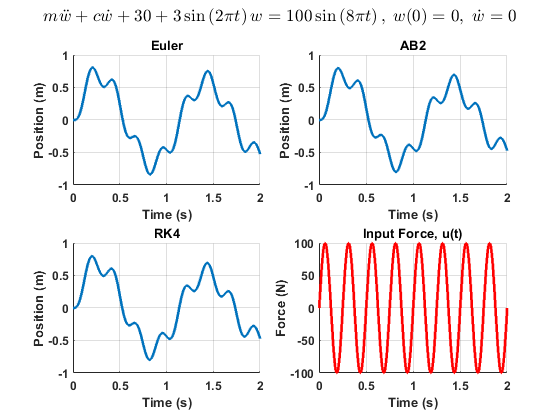

s2 = {@f2,@y2,@u2,[0, 0]};

msd = '$m\ddot{w}+c\dot{w}+30+3\sin\left(2\pi{}t\right)w = 100\sin\left(8\pi{}t\right), \: w(0) = 0, \; \dot{w} = 0$';

[OutE.t,  OutE.y,  OutE.u]     = mySim(s2, 2.0, 0.005, 'euler');
[OutAB.t, OutAB.y, OutAB.u]    = mySim(s2, 2.0, 0.005, 'ab2');
[OutRK4.t, OutRK4.y, OutRK4.u] = mySim(s2, 2.0, 0.005, 'rk4');

OutE.y   = OutE.y(:, 1); % Only look at position, as if it's correct the derivitive will be as well.
OutAB.y  = OutAB.y(:, 1); 
OutRK4.y = OutRK4.y(:, 1); 

figure()
subplot(2, 2, 1)
sgtitle(msd, 'Interpreter','latex')

hold on
title("Euler")
[x, y] =   stairs(OutE.t, OutE.y);
plot(x, y, 'LineWidth',2)

set(gca, 'FontWeight', 'Bold')
grid
ylabel("Position (m)")
xlabel("Time (s)")
hold off

subplot(2, 2, 2)
hold on
title("AB2")

[x, y] =   stairs(OutAB.t, OutAB.y);
plot(x, y, 'LineWidth',2)

set(gca, 'FontWeight', 'Bold')
grid
ylabel("Position (m)")
xlabel("Time (s)")
hold off

subplot(2, 2, 3)
hold on
title("RK4")

[x, y] =   stairs(OutRK4.t, OutRK4.y);
plot(x, y, 'LineWidth',2)

set(gca, 'FontWeight', 'Bold')
grid
ylabel("Position (m)")
xlabel("Time (s)")
hold off
subplot(2, 2, 4)
hold on

[x, y] = stairs(OutRK4.t, OutRK4.u);
plot(x, y, 'r', 'LineWidth', 2)

set(gca, 'FontWeight', 'Bold')
grid
title("Input Force, u(t)")
xlabel("Time (s)")
ylabel("Force (N)")
hold off

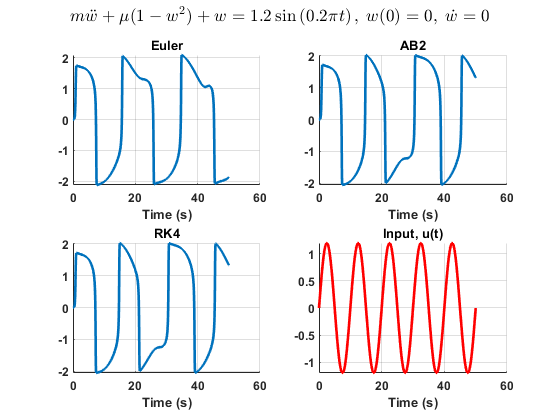

s3 = {@f3,@y3,@u3,[0, 0]};

vdp = '$m\ddot{w}+\mu(1-w^2)+w = 1.2\sin\left(0.2\pi{}t\right), \: w(0) = 0, \; \dot{w} = 0$';

[OutE.t,  OutE.y,  OutE.u]     = mySim(s3, 50, 0.01, 'euler');
[OutAB.t, OutAB.y, OutAB.u]    = mySim(s3, 50, 0.01, 'ab2');
[OutRK4.t, OutRK4.y, OutRK4.u] = mySim(s3, 50, 0.01, 'rk4');

OutE.y   = OutE.y(:, 1); % Only look at position, as if it's correct the derivitive will be as well.
OutAB.y  = OutAB.y(:, 1); 
OutRK4.y = OutRK4.y(:, 1); 

figure()

subplot(2, 2, 1)
sgtitle(vdp, 'Interpreter','latex')

hold on
title("Euler")
[x, y] =   stairs(OutE.t, OutE.y);
plot(x, y, 'LineWidth', 2)

set(gca, 'FontWeight', 'Bold')
grid
xlabel("Time (s)")
hold off

subplot(2, 2, 2)
hold on
title("AB2")

[x, y] =   stairs(OutAB.t, OutAB.y);
plot(x, y, 'LineWidth', 2)

set(gca, 'FontWeight', 'Bold')
grid
xlabel("Time (s)")
hold off

subplot(2, 2, 3)
hold on
title("RK4")

[x, y] =   stairs(OutRK4.t, OutRK4.y);
plot(x, y, 'LineWidth', 2)

set(gca, 'FontWeight', 'Bold')
grid
xlabel("Time (s)")
hold off

subplot(2, 2, 4)
hold on

[x, y] = stairs(OutRK4.t, OutRK4.u);
plot(x, y, 'r', 'LineWidth', 2)

set(gca, 'FontWeight', 'Bold')
grid
title("Input, u(t)")
xlabel("Time (s)")
hold off

Each plot shows the three different integration methods, and the input to the systems. The input is independent of the integration technique as it only varies on time, not based upon the previous state.

From the above plots, the second system looks the same for all integration techniques. If compared more deeply, such as calculating the root sum squared error between the techniques, a difference would be able to be found, but it would not be large. For the third system, the Van der Pol oscillator, there is a difference that can be seen. This simulation ran at 0.01 seconds per step, and for AB2 and RK4 there are indistinguiable. The Euler variant though is obviously different. The tops of the peaks are caved-in, which is a very significant difference. While not shown here, if the time step is decreased to 0.001 seconds per step, this "caved-in" feature goes away. This means that for the Van der Pol oscillator Euler integration should not be used at step sizes as large as 0.01 seconds. A more sophisticated techinque must be used.

## Conclusion

This project resulted in functions for simulating differential equations, and comparing the different solvers. It can be seen above the for the Van der Pol oscillator that the Euler integration is visibly different from the other, more accurate, integration techniques. All of the integrators were validated with an ODE that has a closed-form solution, meaning the the results from these integrators can be at minimum trusted with an LTI differential equation system. Verification against other students' data brings the confidence of the integrators higher. For future work, validation against more types of systems would be the best route, as jsut validating against a single type may not be the best choice if high accuracy with more complicated systems is warrented.  But overall the trust is high due to the low probability of multiple students making the same mistake.

## Appendix A

%% Test Simulator Code
% This script runs Euler, AB2, and RK4 integrators with three test systems.
% After the systems are simualted, they are plotted. One system has a known
% closed-form solution, and so the plots with it also include the
% close-form solution for validation of the integrators.

%%
% Cleanup
clearvars;
close all

%%
% Define the dynamic system model
% x' = f1(x,u,t) where f1 and u1(t) are MATLAB functions
% y1(x,u,t) is also a MATLAB function 
s1 = {@f1,@y1,@u1,2.0};
s2 = {@f2,@y2,@u2,[0, 0]};
s3 = {@f3,@y3,@u3,[0, 0]};
 
% Validation data
validTime = 0:0.0001:2;
validData = 2 * exp(-4 * validTime); % Closed form solution.

%%
% Simulate the dynamic systems where the second and third arguments are the
% final time and time step respectively.

[OutE.s1.t,  OutE.s1.y,  OutE.s1.u]     = mySim(s1, 2.0, 0.05, 'euler');
[OutAB.s1.t, OutAB.s1.y, OutAB.s1.u]    = mySim(s1, 2.0, 0.05, 'ab2');
[OutRK4.s1.t, OutRK4.s1.y, OutRK4.s1.u] = mySim(s1, 2.0, 0.05, 'rk4');

[OutE.s2.t,  OutE.s2.y,  OutE.s2.u]     = mySim(s2, 10, 0.005, 'euler');
[OutAB.s2.t, OutAB.s2.y, OutAB.s2.u]    = mySim(s2, 10, 0.005, 'ab2');
[OutRK4.s2.t, OutRK4.s2.y, OutRK4.s2.u] = mySim(s2, 10, 0.005, 'rk4');


[OutE.s3.t,  OutE.s3.y,  OutE.s3.u]     = mySim(s3, 50, 0.01, 'euler');
[OutAB.s3.t, OutAB.s3.y, OutAB.s3.u]    = mySim(s3, 50, 0.01, 'ab2');
[OutRK4.s3.t, OutRK4.s3.y, OutRK4.s3.u] = mySim(s3, 50, 0.01, 'rk4');

OutE.s2.y   = OutE.s2.y(:, 1); % Only look at position, as if it's correct the derivitive will be as well.
OutAB.s2.y  = OutAB.s2.y(:, 1); 
OutRK4.s2.y = OutRK4.s2.y(:, 1); 

OutE.s3.y   = OutE.s3.y(:, 1); % Only look at position, as if it's correct the derivitive will be as well.
OutAB.s3.y  = OutAB.s3.y(:, 1); 
OutRK4.s3.y = OutRK4.s3.y(:, 1); 

%% Plot the validated system with the known data.
expo = '$\dot{x} = -4x, \; x(0) = 2$';

h = plotData(OutE.s1, expo, 'Euler');
hold on
plot(validTime, validData)
legend('y', 'u', 'Closed-form Solution')
hold off

h = plotData(OutAB.s1, expo, 'AB2');
hold on
plot(validTime, validData)
legend('y', 'u', 'Known Solution')
hold off

h = plotData(OutRK4.s1, expo, 'RK4');
hold on
plot(validTime, validData)
legend('y', 'u', 'Known Solution')
hold off

%% Plot the other systems.
msd = '$m\ddot{w}+c\dot{w}+30+3\sin\left(2\pi{}t\right)w = 100\sin\left(8\pi{}t\right), \: w(0) = 0, \; \dot{w} = 0$';
% Plot mass-spring-damper
h = plotData(OutE.s2, msd, 'Euler');
h = plotData(OutAB.s2, msd, 'AB2');
h = plotData(OutRK4.s2, msd, 'RK4');

vdp = '$m\ddot{w}+\mu(1-w^2)+w = 1.2\sin\left(0.2\pi{}t\right), \: w(0) = 0, \; \dot{w} = 0$';
% Plot Van de Pol Oscillator

h = plotData(OutE.s3, vdp, 'Euler');
h = plotData(OutAB.s3, vdp, 'AB2');
h = plotData(OutRK4.s3, vdp, 'RK4');

%% Helper Functions


function h = plotData(dat, equation, integrator)
% dat is assumed to be a structure with fields: t, y, and u. The function
% returns a handle to the figure
  FS = 14; % font size
  LW =  2; % line width
  figs =  findobj('type','figure'); % find all the open figures
  id = length(figs) + 1; % create an id for this fig

  h.fig   = figure(id); % create figure
  h.axs   = axes;       % create axes
  [x,y] =   stairs(dat.t,dat.y); % create stair data
  h.ln(1) = line(x,y,'Color','k'); % plot the stair data
  [x,y] =   stairs(dat.t,dat.u);
  h.ln(2) = line(x,y,'Color','b');

  h.xlb   = xlabel('Time (s)');
  h.ylb   = ylabel('In and Out');
  h.ttl   = title({equation, integrator});
  h.leg   = legend('y','u');
  grid;
  h.axs.FontWeight  = 'Bold';
  h.axs.FontSize    = FS;
  for i=1:length(h.ln)
    h.ln(i).LineWidth = LW;
  end
  h.ttl.Interpreter = 'LaTeX';

end